file1 = 'doc/examples/ttc/drivebrake.mat';
file2 = 'doc/examples/ttc/cornering.mat';
parser = tydex.parsers.FSAETTC_SI_ISO_Mat();
measurements1 = parser.run(file1);
measurements2 = parser.run(file2);
measurements = [measurements1 measurements2];
measurements = measurements.downsample(10);

tyre = MagicFormulaTyre();
tyre.Parameters.NOMPRES.Value = max([measurements.NOMPRES]);
tyre.Parameters.FNOMIN.Value = max([measurements.FNOMIN]);
tyre.Parameters.UNLOADED_RADIUS.Value = 0.2025;

options = optimset('fmincon');
options.MaxFunctionEvaluations = 1000;
options.MaxIter = 30;

fitmodes = {'Fx0','Fy0','Fx','Fy'};
tyre.fit(measurements, fitmodes, options)

Fitting Fx0...

Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 3.000000e+01.

Finished Fit-Mode: Fx0
Time elapsed 12.9s.

Fitting Fy0...

Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 3.000000e+01.

Finished Fit-Mode: Fy0
Time elapsed 18.5s.

Fitting Fx...

Solver stopped prematurely.

fmincon stopped because it exceeded the iteration limit,
options.MaxIterations = 3.000000e+01.

Finished Fit-Mode: Fx
Time e

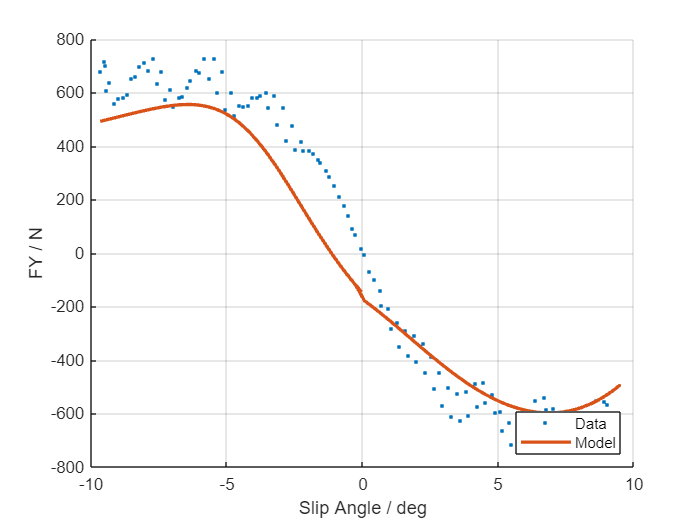

n = numel(measurements);
measurement = measurements(180);
[SX,SA,FZ,IP,IA,VX,FX,FY,MZ,MY,MX] = unpack(measurement);
[FX_mdl, FY_mdl, MZ_mdl, MY_mdl, MX_mdl] = magicformula(tyre,SX,SA,FZ,IP,IA,VX);

constants = {measurement.Constant.Name};
figure(); grid on; hold on
if any(contains(constants, 'SLIPANGL'))
    plot(SX, FX, '.')
    plot(SX, FX_mdl, '-', 'LineWidth', 2)
    ylabel('FX / N')
    xlabel('Slip Ratio / 1')
else
    plot(rad2deg(SA), FY, '.')
    plot(rad2deg(SA), FY_mdl, '-', 'LineWidth', 2)
    ylabel('FY / N')
    xlabel('Slip Angle / deg')
end
legend Data Model Location southeast

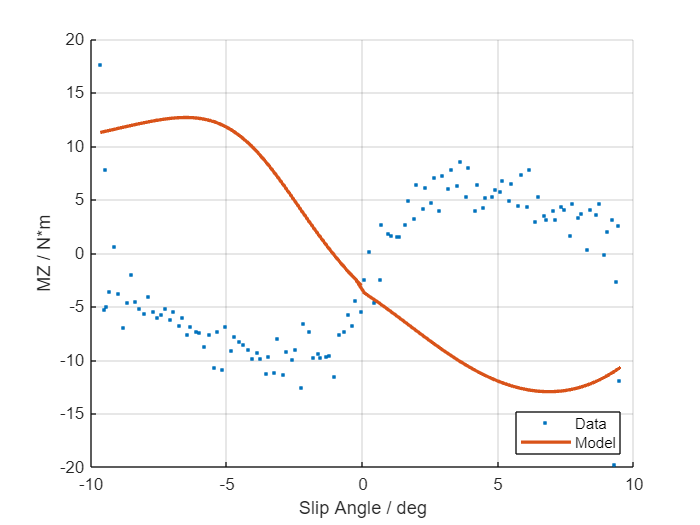


figure(); grid on; hold on
if any(contains(constants, 'SLIPANGL'))
    plot(SX, MZ, '.')
    plot(SX, MZ_mdl, '-', 'LineWidth', 2)
    ylabel('MZ / N*m')
    xlabel('Slip Ratio / 1')
else
    plot(rad2deg(SA), MZ, '.')
    plot(rad2deg(SA), MZ_mdl, '-', 'LineWidth', 2)
    ylabel('MZ / N*m')
    xlabel('Slip Angle / deg')
end
legend Data Model Location southeast

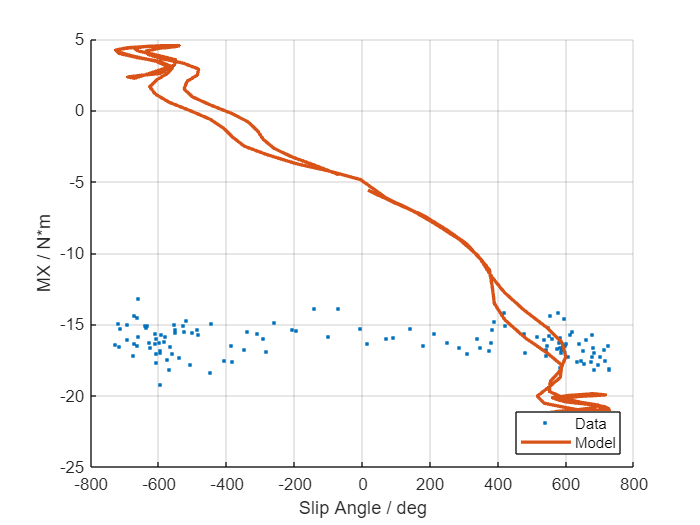


figure(); grid on; hold on
if any(contains(constants, 'SLIPANGL'))
    plot(SX, MX, '.')
    plot(SX, MX_mdl, '-', 'LineWidth', 2)
    ylabel('MX / N*m')
    xlabel('Slip Ratio / 1')
else
    plot(FY, MX, '.')
    plot(FY, MX_mdl, '-', 'LineWidth', 2)
    ylabel('MX / N*m')
    xlabel('Slip Angle / deg')
end
legend Data Model Location southeast